% initialize the values
x_bar = zeros(2,1)

x_bar =      0
     0


P = 25 * eye(2)

P =     25     0
     0    25



H_r = eye(2)

H_r =      1     0
     0     1


H_c = eye(2)

H_c =      1     0
     0     1



R_c = [79, 36; 36, 36]

R_c =     79    36
    36    36


R_r = [28, 4; 4, 22]

R_r =     28     4
     4    22



z_c = [2; 14]

z_c =      2
    14


z_r = [-4; 6]

z_r =     -4
     6


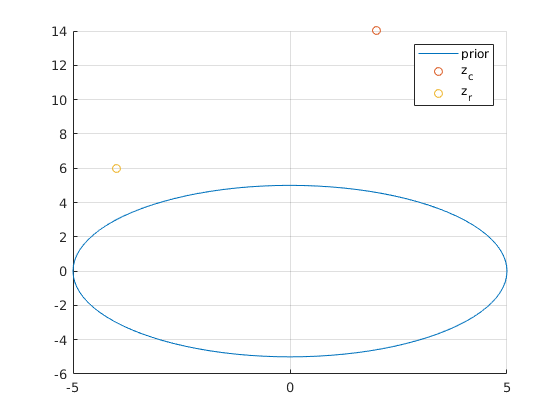


% set up for plotting ellipses
Npts = 100; % number of points around the circle
circle = [cos( 0:(2*pi/Npts):(2*pi) ); sin( 0:(2*pi/Npts):(2*pi) )];

% initial 1 sigma ellipses
figure(1); clf; hold on; grid on;
data = x_bar + chol(P)' * circle;
plot(data(1,:), data(2, :), 'DisplayName','prior')

% measurements 
scatter(z_c(1), z_c(2), 'DisplayName', 'z_c')
scatter(z_r(1), z_r(2), 'DisplayName', 'z_r')

legend()

% You can make some functions to ease the conditionioning
% FILL IN THE DOTS ...
condition_mean = @(x_bar, z, P, H, R) x_bar + P*(H*P*H' + R)^(-1)*(z-x_bar);
condition_cov = @(P, H, R) P - H*P*(H*P*H' + R)^(-1)*P*H';

% task 5 (f)
% FILL IN FOR THE DOTS ...

% condition on camera
x_bar_c = condition_mean(x_bar, z_c, P, H_c, R_c)

x_bar_c =    -1.8918
    6.8542


P_c = condition_cov(P, H_c, R_c)

P_c =    17.4475    4.4572
    4.4572   12.1236



% condition on radar
x_bar_r = condition_mean(x_bar, z_r, P, H_r, R_r)

x_bar_r =    -2.1414
    3.3737


P_r = condition_cov(P, H_r, R_r)

P_r =    13.1313    1.0101
    1.0101   11.6162


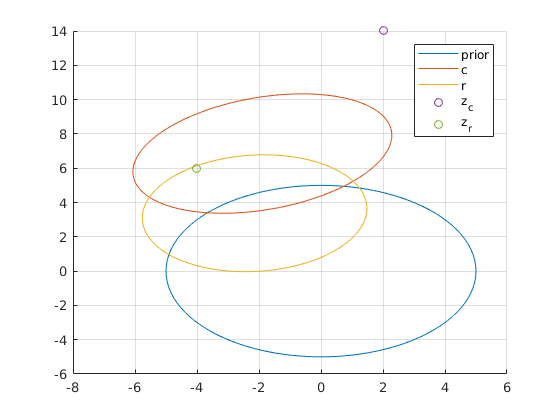


% Plot 1 sigma ellipses
figure(2); clf; hold on; grid on;

data = x_bar + chol(P)' * circle;
plot(data(1,:), data(2, :), 'DisplayName','prior')

data = x_bar_c + chol(P_c)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'c')

data = x_bar_r + chol(P_r)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'r')

% measurements
scatter(z_c(1), z_c(2), 'DisplayName', 'z_c')
scatter(z_r(1), z_r(2), 'DisplayName', 'z_r')
legend()

% task 5 (g)

% condition the already camera conditioned on the radar
x_bar_cr = condition_mean(x_bar_c, z_r, P_c, H_r, R_r)

x_bar_cr =    -2.7183
    6.4872


P_cr =  condition_cov(P_c, H_r, R_r)

P_cr =    10.7043    2.3261
    2.3261    7.7676



% condition the already radar conditioned on the camera
x_bar_rc = condition_mean(x_bar_r, z_c, P_r, H_c, R_c)

x_bar_rc =    -2.7183
    6.4872


P_rc = condition_cov(P_r, H_c, R_c)

P_rc =    10.7043    2.3261
    2.3261    7.7676


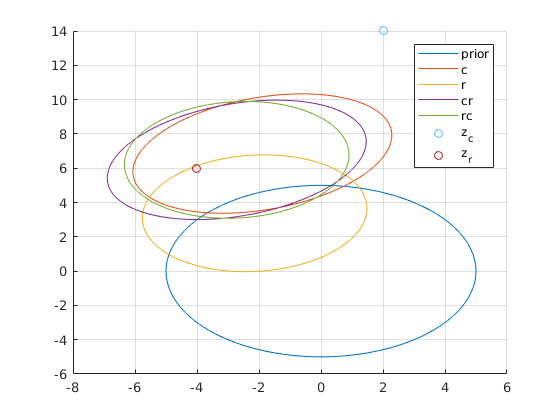


% Plot 1 sigma ellipses
figure(3); clf; hold on; grid on;

data = x_bar + chol(P)' * circle; 
plot(data(1,:), data(2, :), 'DisplayName','prior')

data = x_bar_c + chol(P_c)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'c')

data = x_bar_r + chol(P_r)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'r')

data = x_bar_cr + chol(P_c)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'cr')

data = x_bar_rc + chol(P_r)' * circle;
plot(data(1,:), data(2, :), 'DisplayName', 'rc')

% meausrements
scatter(z_c(1), z_c(2), 'DisplayName', 'z_c')
scatter(z_r(1), z_r(2), 'DisplayName', 'z_r')

legend()

normcdf([6,-4],x_bar_rc,P_rc)

ans =     0.7923    0.2908
    0.4171    0.0885
